clear all
close all
clc

rng('default');

datasize = 3000;
inz = smoothdata(rand(datasize,1),'gaussian',5);



% Choose parameters
% rng(2)
n=2; m=2;
mn = n+m;

inlags=[1 2 3 4];
outlags =[0 1 2 3 4];

d=numel(inlags)+numel(outlags)-1;

maxranksynth =5;
rk = (min(min(mn.^[0:d],mn.^[d:-1:0]),maxranksynth));

scale = 9;
synth = 0.5+ scale*(double(rand(mn*ones(1,d))>0.5)-0.5);

TN = trunttsvd(synth,rk)

TN = struct with fields:
    core: {[1×4×4 double]  [4×4×5 double]  [5×4×5 double]  [5×4×5 double]  [5×4×5 double]  [5×4×5 double]  [5×4×4 double]  [4×4 double]}
      sz: [8×3 double]



norm(TN.core{end})

ans = 137.1025

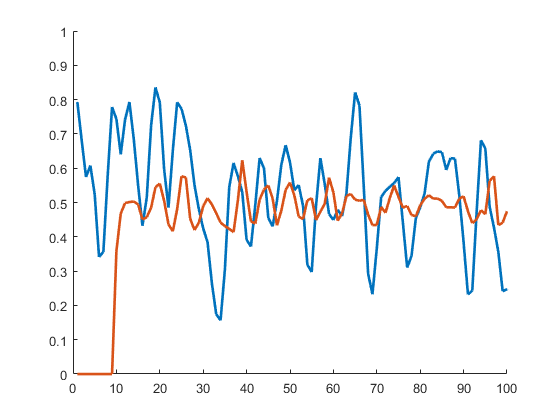


% siminput(1:21)=heaviside(-10:10)/2;
siminput = inz;
simoutput = zeros(datasize,1);

% siminput = 1*ones(1000,1);
% siminput = 0.2*sin(1:0.01:11)'+0.5;

for j = 10:datasize
simfeaturez = [simoutput(j-outlags(2:end))' siminput(j-inlags(1:end))'];
% simfeaturez(simfeaturez<0)=0;
% simfeaturez(simfeaturez>1)=1;
simoutput(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
plot(siminput,'Linewidth',2)
plot(simoutput,'Linewidth',2)
% plot((inz(11)/simoutput(11))*simoutput)
hold off
axis([0 100 0 1])

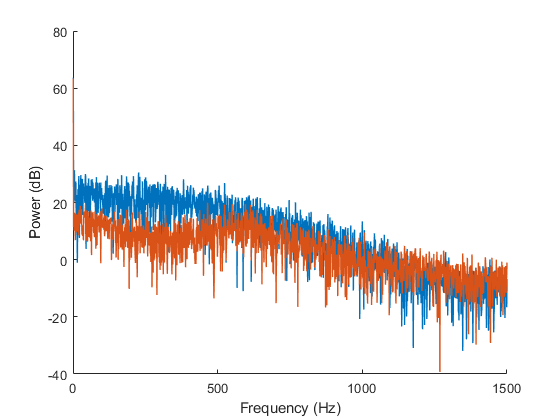


FX = mag2db(abs(fft(siminput)));
FY = mag2db(abs(fft(simoutput)));
figure;
hold on
plot(FX(1:floor(end/2)),'Linewidth',1)
plot(FY(1:floor(end/2)),'Linewidth',1)
hold off
xlabel('Frequency (Hz)')
ylabel('Power (dB)')

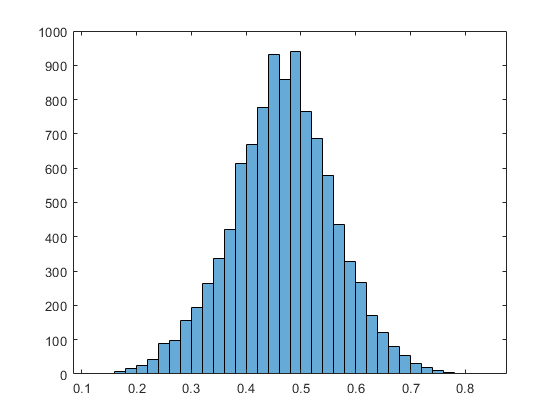


testfeatures = rand(10000,8);
testput = evalspline(TN,testfeatures,n,m);
histogram(testput')

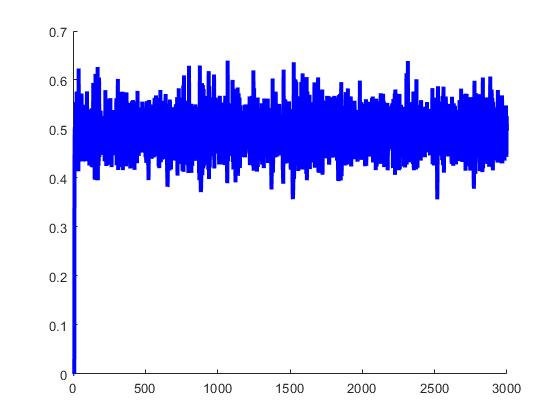


figure;
hold on
plot(simoutput,'Linewidth',3, "Color",[0 0 1])


SNR = [10 0 -10]

SNR =     10     0   -10


colr = flipud(0.7*eye(3)+0.3)

colr =     0.3000    0.3000    1.0000
    0.3000    1.0000    0.3000
    1.0000    0.3000    0.3000


% for period = 1:numel(SNR)
% 
% plotnoise = addnoise(simoutput,SNR(period));
% plot(plotnoise,'Linewidth',1.5, "Color",colr(period,:))
% end
% hold off
% axis([100 150 0 1])
% 
% legend('True', 'SNR=10','SNR=0','SNR=-10')



SNR = [30 25 20 15 10 5 0 -5 -10]

SNR =     30    25    20    15    10     5     0    -5   -10



for period = 1:numel(SNR)

simoutputnoise = addnoise(simoutput,SNR(period));



input = siminput(10:2000);
output = simoutputnoise(10:2000);

tinput = siminput(2001:end);
toutput = simoutput(2001:end);
toutputnoise = simoutputnoise(2001:end);


Preprocessing Data

[featurez,zeta,tfeaturez,yt] = lagfeatures(input,tinput,output,toutput,inlags,outlags);


Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 2;                  %degree B-spline
m = 2;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);




Initialize tensor train -----------------------------------------------------------------

% Choose TT-ranks
maxrank =5;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

for trial = 1:4

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


% Pcount = (In)^d;                    %Original tensor size
% dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
% disp(['Compression: ' num2str(dof/Pcount)]);  %ratio


Optimize TT cores

% lambda=1*10^-8;
LAMBDA = [10^-3 10^-4 10^-8];

for nmr = 1:3
lambda= LAMBDA(nmr);

difforder=2;
MAXITR = 2*d;


% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,difforder);


Evaluate Test data


yhat = evalspline(TN,tfeaturez,n,m);

RMSE_P(period,nmr,trial) = sqrt(immse(yhat,yt));


% siminputz = tinput;
% simoutputz = toutputnoise(1:outlags(end));
% numz = numel(outlags);
% for j = (outlags(end)+1):1000
% simfeaturez = [simoutputz(j-outlags(2:end))' siminputz(j-outlags(2:end))'];
% simfeaturez(simfeaturez<0)=0;
% simfeaturez(simfeaturez>1)=1;
% simoutputz(j) = evalspline(TN,simfeaturez,n,m);
% end

[simoutputz] = simnarx(TN,tinput,toutputnoise,inlags,outlags,n,m);

RMSE_S(period,nmr,trial) = sqrt(immse(toutput,simoutputz));

toc

Elapsed time is 1.048525 seconds.
Elapsed time is 0.858306 seconds.
Elapsed time is 0.772873 seconds.
Elapsed time is 0.815119 seconds.
Elapsed time is 0.643836 seconds.
Elapsed time is 0.605204 seconds.
Elapsed time is 0.615105 seconds.
Elapsed time is 0.693043 seconds.
Elapsed time is 0.850893 seconds.
Elapsed time is 0.654755 seconds.
Elapsed time is 0.691252 seconds.
Elapsed time is 0.611990 seconds.
Elapsed time is 0.646046 seconds.
Elapsed time is 0.621690 seconds.
Elapsed time is 0.634852 seconds.
Elapsed time is 0.701998 seconds.
Elapsed time is 0.617977 seconds.
Elapsed time is 0.609635 seconds.
Elapsed time is 0.631090 seconds.
Elapsed time is 0.638330 seconds.
Elapsed time is 0.786535 seconds.


end
end
end

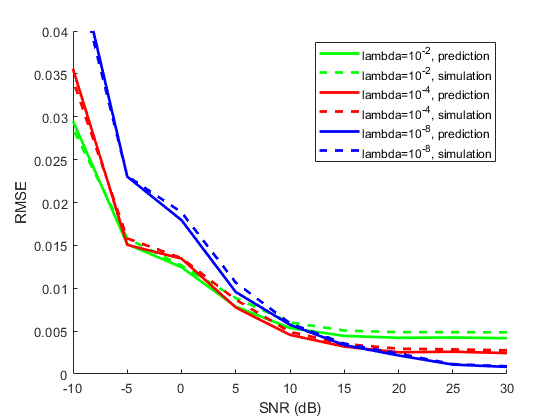

figure;

RMSE_Plot = mean(RMSE_P,3);
RMSE_Slot = mean(RMSE_S,3);

hold on
plot(SNR,RMSE_Plot(:,1),'Linewidth',2,"Color",'g')
plot(SNR,RMSE_Slot(:,1),'Linewidth',2,"Color",'g',"LineStyle","--")
plot(SNR,RMSE_Plot(:,2),'Linewidth',2,"Color",'r')
plot(SNR,RMSE_Slot(:,2),'Linewidth',2,"Color",'r',"LineStyle","--")
plot(SNR,RMSE_Plot(:,3),'Linewidth',2,"Color",'b')
plot(SNR,RMSE_Slot(:,3),'Linewidth',2,"Color",'b',"LineStyle","--")
% plot(SNR,RMSE_Slot(:,2))
hold off
xlabel('SNR (dB)')
ylabel('RMSE')
legend('lambda=10^{-2}, prediction','lambda=10^{-2}, simulation','lambda=10^{-4}, prediction', 'lambda=10^{-4}, simulation','lambda=10^{-8}, prediction','lambda=10^{-8}, simulation')
axis([-10 30 0 0.04])

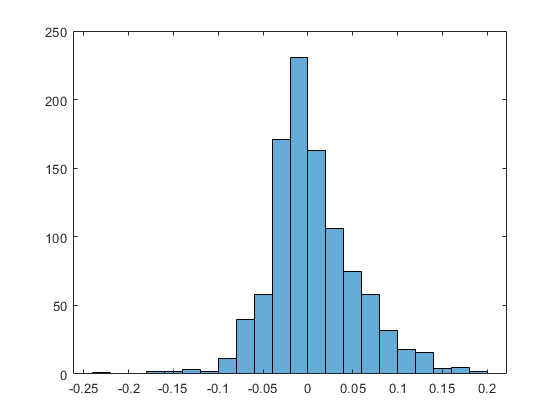



histogram(toutput-simoutputz)